# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Input Signals1

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
clear inputPath latestSlow latestFast
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Globals

delta_t = t(2)-t(1);
delta_pureSinTime = pureSinTime(2)-pureSinTime(1);
KpStatic = 1;
KiStatic = 10;
tdStatic=0.04;

# Toggles

togRMSFreq = 0;
togSinglePoint = 1;
megaSweep = 0;  
figurePath = strcat(commonPath,'\Golden Figures');

# Model

%Model Setup
tend = num2str(pureSinTime(end));
stepsize = num2str(delta_pureSinTime);
simName = 'HybridSaccadeFF';

open_system(simName)
set_param(simName,'StartTime','0','StopTime',tend,'FixedStep',stepsize) %'SimulationMode','accelerator','SimCompilerOptimization','on'
save_system(simName)

# Single Point Hybrid / Smooth comparison

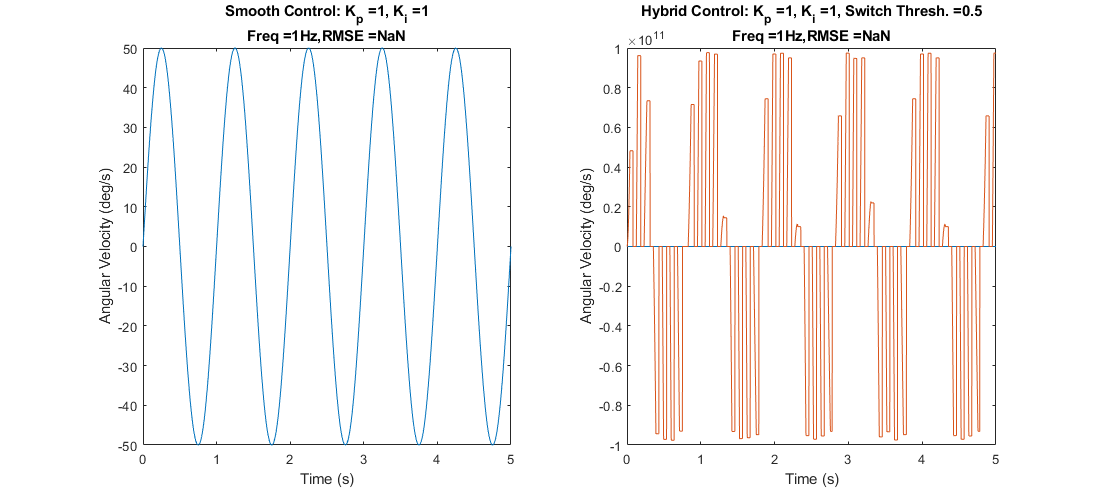

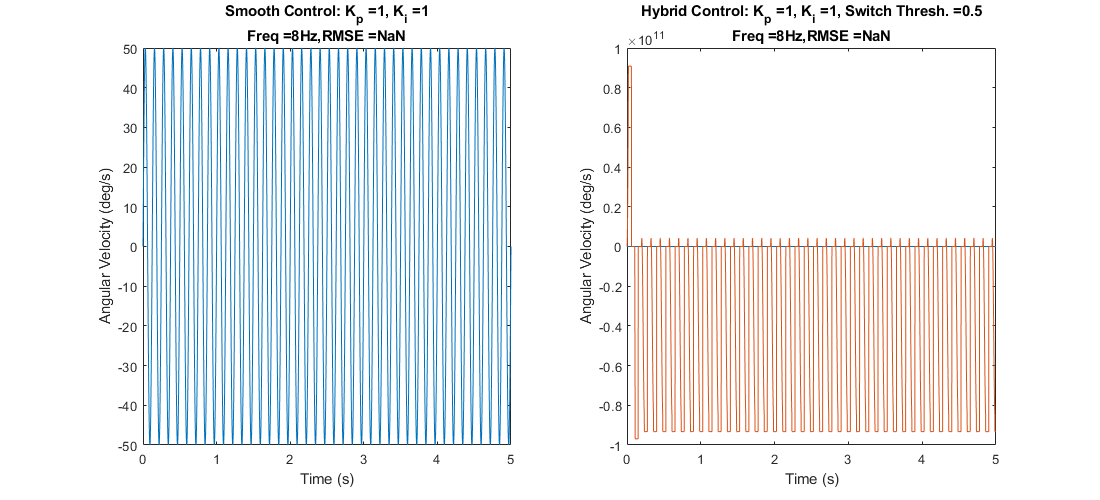

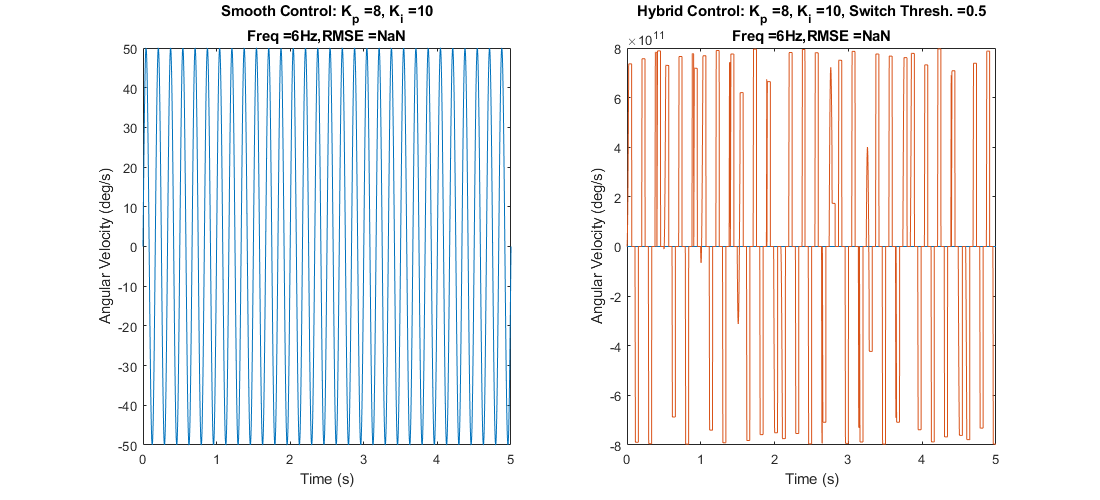

Unrecognized function or variable 'pureSineTime'.

if togSinglePoint == 1
    
   freqindex = 10;
   Kp = 1;
   Ki = 1;
   td =tdStatic;
   switchThresh = 0.5;
   T_lim_up = inf;
   T_lim_low = -inf;
   [smoothOut10, hybridOut10] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainlowfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 80;
    [smoothOut80, hybridOut80] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\lowgainhighfreq')
%    export_fig (savePath,'-eps')
    
    freqindex = 60;
    Kp = 8;
    Ki = 10;
    [smoothOut60, hybridOut60] = singlePointCompare(Kp,Ki,td,switchThresh,freqindex,sinfreqs,pureSinTime,pureSin,...
       G_plant,T_lim_up,T_lim_low,simName);
%    savePath =strcat(figurePath,'\SinglePointHybrid\highgainmedfreq')
%    export_fig (savePath,'-eps')
    
    sineFit(hybridOut60(freqindex,:),pureSineTime)
end

# Ridiculous Sweep (All params minus td = 0.04)

if megaSweep == 1  
    set_param(simName,'StopTime',num2str(pureSinTime(end)),'FixedStep',num2str(pureSinTime(2) - pureSinTime(1))...
        ,'FastRestart','on')
    save_system(simName)
    
    td = 0.04
    [nump,denp]=padeWrap(td);
    d_tf = tf(nump,denp);
    
    Kp = .1:1:20;
    Ki = .1:1:20;
    switchThresh = 0:0.5:5;
    decimationFactor = 5;
    pureSinDecimate = pureSin(1:decimationFactor:end, :);
    sinfreqsDecimate = sinfreqs(1:decimationFactor:end);
    
    innerSize = length(Kp)*length(Ki)*length(switchThresh);
    tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
    
    %FFT Params
    Fs = 1/(pureSinTime(2)-pureSinTime(1));
    N = 10000;   
    
    sweepData = repmat(struct('Kp',-1,'Ki',-1,'switchThresh',-1,'inputFreq',-1,'sError',-1,'hError',-1, ...
        'smoothOut',-1000*ones(1,length(pureSinTime)),'hybridOut',-1000*ones(1,length(pureSinTime)),'sGain',-1,...
        'sPhase',-1,'hGain',-1,'hPhase',-1,'hFit',-1000*ones(1,length(pureSinTime)),'rsquare',-1),length(Kp),...
        length(Ki),length(switchThresh),size(pureSinDecimate,1));
    
    figure
    remaining = length(Kp)*length(Ki);
    for i = 1:length(Kp)
        for j = 1:length(Ki)
            tic
            sweepData= simTrackSmoothPrefill(Kp(i),Ki(j),d_tf,G_plant,pureSinDecimate,pureSinTime,sinfreqsDecimate,...
                sweepData,i,j,length(switchThresh),Fs,N);
            
            for k = 1:length(switchThresh)
                sweepData = simTrack(Kp(i),Ki(j),td,switchThresh(k),G_plant,pureSinDecimate,...
                    pureSinTime,sinfreqsDecimate,tLimSet,simName,sweepData,i,j,k,Fs,N);
            end
            toc
            remaining = remaining-1
        end
    end
    basepath = strcat(commonPath,'\Hybrid Performance Results');
        savePath = genFileName(basepath,'megaSweep');
        save(savePath,'sweepData','Kp','Ki','switchThresh','sinfreqsDecimate','pureSinTime','-v7.3')
end

td = 0.0400

Elapsed time is 23.406629 seconds.


remaining = 399

Elapsed time is 21.622925 seconds.


remaining = 398

Elapsed time is 21.661787 seconds.


remaining = 397

Elapsed time is 21.696737 seconds.


remaining = 396

Elapsed time is 21.732560 seconds.


remaining = 395

Elapsed time is 21.740049 seconds.


remaining = 394

Elapsed time is 21.874596 seconds.


remaining = 393

Elapsed time is 21.910934 seconds.


remaining = 392

Elapsed time is 21.937226 seconds.


remaining = 391

Elapsed time is 21.939662 seconds.


remaining = 390

Elapsed time is 21.951231 seconds.


remaining = 389

Elapsed time is 22.068390 seconds.


remaining = 388

Elapsed time is 22.186596 seconds.


remaining = 387

Elapsed time is 22.409077 seconds.


remaining = 386

Elapsed time is 22.467302 seconds.


remaining = 385

Elapsed time is 22.556930 seconds.


remaining = 384

Elapsed time is 22.769001 seconds.


remaining = 383

Elapsed time is 22.890846 seconds.


remaining = 382

Elapsed time is 23.076009 seconds.


remaining = 381

Elapsed time is 23.184228 seconds.


remaining = 380

Elapsed time is 23.441372 seconds.


remaining = 379

Elapsed time is 23.699338 seconds.


remaining = 378

Elapsed time is 24.280880 seconds.


remaining = 377

Elapsed time is 24.490778 seconds.


remaining = 376

Elapsed time is 24.812928 seconds.


remaining = 375

Elapsed time is 24.894830 seconds.


remaining = 374

Elapsed time is 25.102536 seconds.


remaining = 373

Elapsed time is 25.358300 seconds.


remaining = 372

Elapsed time is 25.571165 seconds.


remaining = 371

Elapsed time is 25.868091 seconds.


remaining = 370

Elapsed time is 25.962905 seconds.


remaining = 369

Elapsed time is 26.347228 seconds.


remaining = 368

Elapsed time is 26.445116 seconds.


remaining = 367

Elapsed time is 26.547159 seconds.


remaining = 366

Elapsed time is 26.633045 seconds.


remaining = 365

Elapsed time is 26.937270 seconds.


remaining = 364

Elapsed time is 27.153146 seconds.


remaining = 363

Elapsed time is 27.148943 seconds.


remaining = 362

Elapsed time is 27.057251 seconds.


remaining = 361

Elapsed time is 27.340909 seconds.


remaining = 360

Elapsed time is 27.550940 seconds.


remaining = 359

Elapsed time is 27.571122 seconds.


remaining = 358

Elapsed time is 29.865057 seconds.


remaining = 357

Elapsed time is 28.330787 seconds.


remaining = 356

Elapsed time is 28.696593 seconds.


remaining = 355

Elapsed time is 28.244994 seconds.


remaining = 354

Elapsed time is 28.149374 seconds.


remaining = 353

Elapsed time is 28.268414 seconds.


remaining = 352

Elapsed time is 28.588028 seconds.


remaining = 351

Elapsed time is 30.603115 seconds.


remaining = 350

Elapsed time is 29.365879 seconds.


remaining = 349

Elapsed time is 29.182693 seconds.


remaining = 348

Elapsed time is 29.221892 seconds.


remaining = 347

Elapsed time is 29.367180 seconds.


remaining = 346

Elapsed time is 29.568846 seconds.


remaining = 345

Elapsed time is 29.887830 seconds.


remaining = 344

Elapsed time is 29.764988 seconds.


remaining = 343

Elapsed time is 29.903261 seconds.


remaining = 342

Elapsed time is 29.976006 seconds.


remaining = 341

Elapsed time is 30.183343 seconds.


remaining = 340

Elapsed time is 30.530081 seconds.


remaining = 339

Elapsed time is 30.352294 seconds.


remaining = 338

Elapsed time is 30.679361 seconds.


remaining = 337

Elapsed time is 30.586063 seconds.


remaining = 336

Elapsed time is 30.946646 seconds.


remaining = 335

Elapsed time is 30.864685 seconds.


remaining = 334

Elapsed time is 31.255399 seconds.


remaining = 333

Elapsed time is 31.336981 seconds.


remaining = 332

Elapsed time is 31.548291 seconds.


remaining = 331

Elapsed time is 31.676441 seconds.


remaining = 330

Elapsed time is 31.957397 seconds.


remaining = 329

Elapsed time is 32.093590 seconds.


remaining = 328

Elapsed time is 32.026140 seconds.


remaining = 327

Elapsed time is 32.175279 seconds.


remaining = 326

Elapsed time is 32.200790 seconds.


remaining = 325

Elapsed time is 32.428787 seconds.


remaining = 324

Elapsed time is 32.364267 seconds.


remaining = 323

Elapsed time is 32.572872 seconds.


remaining = 322

Elapsed time is 33.101514 seconds.


remaining = 321

Elapsed time is 32.935164 seconds.


remaining = 320

Elapsed time is 32.867810 seconds.


remaining = 319

Elapsed time is 33.679017 seconds.


remaining = 318

Elapsed time is 35.939763 seconds.


remaining = 317

Elapsed time is 33.602616 seconds.


remaining = 316

Elapsed time is 33.443617 seconds.


remaining = 315

Elapsed time is 33.878783 seconds.


remaining = 314

Elapsed time is 33.857371 seconds.


remaining = 313

Elapsed time is 34.097812 seconds.


remaining = 312

Elapsed time is 34.244107 seconds.


remaining = 311

Elapsed time is 34.171573 seconds.


remaining = 310

Elapsed time is 34.660648 seconds.


remaining = 309

Elapsed time is 34.774929 seconds.


remaining = 308

Elapsed time is 34.876004 seconds.


remaining = 307

Elapsed time is 34.911197 seconds.


remaining = 306

Elapsed time is 35.315140 seconds.


remaining = 305

Elapsed time is 35.449372 seconds.


remaining = 304

Elapsed time is 35.422594 seconds.


remaining = 303

Elapsed time is 35.750620 seconds.


remaining = 302

Elapsed time is 35.835445 seconds.


remaining = 301

Elapsed time is 36.065067 seconds.


remaining = 300

Elapsed time is 36.101099 seconds.


remaining = 299

Elapsed time is 36.320742 seconds.


remaining = 298

Elapsed time is 36.083590 seconds.


remaining = 297

Elapsed time is 36.773913 seconds.


remaining = 296

Elapsed time is 36.501406 seconds.


remaining = 295

Elapsed time is 36.410154 seconds.


remaining = 294

Elapsed time is 36.937131 seconds.


remaining = 293

Elapsed time is 37.055443 seconds.


remaining = 292

Elapsed time is 37.012379 seconds.


remaining = 291

Elapsed time is 37.521595 seconds.


remaining = 290

Elapsed time is 37.524418 seconds.


remaining = 289

Elapsed time is 37.755086 seconds.


remaining = 288

Elapsed time is 37.795371 seconds.


remaining = 287

Elapsed time is 37.811999 seconds.


remaining = 286

Elapsed time is 38.551704 seconds.


remaining = 285

Elapsed time is 38.844715 seconds.


remaining = 284

Elapsed time is 38.751440 seconds.


remaining = 283

Elapsed time is 38.643824 seconds.


remaining = 282

Elapsed time is 38.680470 seconds.


remaining = 281

Elapsed time is 38.869860 seconds.


remaining = 280

Elapsed time is 38.953026 seconds.


remaining = 279

Elapsed time is 39.276823 seconds.


remaining = 278

Elapsed time is 39.507905 seconds.


remaining = 277

Elapsed time is 39.782366 seconds.


remaining = 276

Elapsed time is 39.563052 seconds.


remaining = 275

Elapsed time is 40.087990 seconds.


remaining = 274

Elapsed time is 40.525398 seconds.


remaining = 273

Elapsed time is 40.174166 seconds.


remaining = 272

Elapsed time is 40.243694 seconds.


remaining = 271

Elapsed time is 40.656850 seconds.


remaining = 270

Elapsed time is 41.132352 seconds.


remaining = 269

Elapsed time is 40.593185 seconds.


remaining = 268

Elapsed time is 41.080494 seconds.


remaining = 267

Elapsed time is 41.642776 seconds.


remaining = 266

Elapsed time is 41.580703 seconds.


remaining = 265

Elapsed time is 42.030169 seconds.


remaining = 264

Elapsed time is 42.227492 seconds.


remaining = 263

Elapsed time is 42.403353 seconds.


remaining = 262

Elapsed time is 42.296170 seconds.


remaining = 261

Elapsed time is 43.032226 seconds.


remaining = 260

Elapsed time is 42.644281 seconds.


remaining = 259

Elapsed time is 42.634218 seconds.


remaining = 258

Elapsed time is 42.904119 seconds.


remaining = 257

Elapsed time is 43.028355 seconds.


remaining = 256

Elapsed time is 43.754263 seconds.


remaining = 255

Elapsed time is 43.787139 seconds.


remaining = 254

Elapsed time is 44.333050 seconds.


remaining = 253

Elapsed time is 44.274135 seconds.


remaining = 252

Elapsed time is 44.414639 seconds.


remaining = 251

Elapsed time is 44.450051 seconds.


remaining = 250

Elapsed time is 44.846834 seconds.


remaining = 249

Elapsed time is 44.663016 seconds.


remaining = 248

Elapsed time is 44.701115 seconds.


remaining = 247

Elapsed time is 45.267582 seconds.


remaining = 246

Elapsed time is 45.044214 seconds.


remaining = 245

Elapsed time is 45.630440 seconds.


remaining = 244

Elapsed time is 46.838079 seconds.


remaining = 243

Elapsed time is 45.753134 seconds.


remaining = 242

Elapsed time is 46.115662 seconds.


remaining = 241

Elapsed time is 46.333730 seconds.


remaining = 240

Elapsed time is 46.726664 seconds.


remaining = 239

Elapsed time is 45.889119 seconds.


remaining = 238

Elapsed time is 46.835488 seconds.


remaining = 237

Elapsed time is 46.896776 seconds.


remaining = 236

Elapsed time is 47.484460 seconds.


remaining = 235

Elapsed time is 47.965711 seconds.


remaining = 234

Elapsed time is 47.715710 seconds.


remaining = 233

Elapsed time is 48.069784 seconds.


remaining = 232

Elapsed time is 47.921896 seconds.


remaining = 231

Elapsed time is 49.266002 seconds.


remaining = 230

Elapsed time is 48.851894 seconds.


remaining = 229

Elapsed time is 49.205049 seconds.


remaining = 228

Elapsed time is 48.817879 seconds.


remaining = 227

Elapsed time is 48.834062 seconds.


remaining = 226

Elapsed time is 49.261744 seconds.


remaining = 225

Elapsed time is 49.848270 seconds.


remaining = 224

Elapsed time is 49.661125 seconds.


remaining = 223

Elapsed time is 50.714229 seconds.


remaining = 222

Elapsed time is 49.989037 seconds.


remaining = 221

Elapsed time is 50.038936 seconds.


remaining = 220

Elapsed time is 50.718385 seconds.


remaining = 219

Elapsed time is 50.910166 seconds.


remaining = 218

Elapsed time is 51.141333 seconds.


remaining = 217

Elapsed time is 52.130422 seconds.


remaining = 216

Elapsed time is 51.260202 seconds.


remaining = 215

Elapsed time is 52.354132 seconds.


remaining = 214

Elapsed time is 52.794206 seconds.


remaining = 213

Elapsed time is 52.432012 seconds.


remaining = 212

Elapsed time is 53.195657 seconds.


remaining = 211

Elapsed time is 52.596009 seconds.


remaining = 210

Elapsed time is 52.991492 seconds.


remaining = 209

Elapsed time is 54.024643 seconds.


remaining = 208

Elapsed time is 54.060510 seconds.


remaining = 207

Elapsed time is 53.911500 seconds.


remaining = 206

Elapsed time is 54.775268 seconds.


remaining = 205

Elapsed time is 53.806540 seconds.


remaining = 204

Elapsed time is 54.950410 seconds.


remaining = 203

Elapsed time is 54.909044 seconds.


remaining = 202

Elapsed time is 54.467437 seconds.


remaining = 201

Elapsed time is 55.656703 seconds.


remaining = 200

Elapsed time is 55.383470 seconds.


remaining = 199

Elapsed time is 55.606523 seconds.


remaining = 198

Elapsed time is 56.381472 seconds.


remaining = 197

Elapsed time is 56.272461 seconds.


remaining = 196

Elapsed time is 56.794542 seconds.


remaining = 195

Elapsed time is 56.468358 seconds.


remaining = 194

Elapsed time is 56.547529 seconds.


remaining = 193

Elapsed time is 57.384643 seconds.


remaining = 192

Elapsed time is 56.925897 seconds.


remaining = 191

Elapsed time is 57.910483 seconds.


remaining = 190

Elapsed time is 58.157808 seconds.


remaining = 189

Elapsed time is 58.290472 seconds.


remaining = 188

Elapsed time is 59.266364 seconds.


remaining = 187

Elapsed time is 58.835563 seconds.


remaining = 186

Elapsed time is 60.018126 seconds.


remaining = 185

Elapsed time is 59.763869 seconds.


remaining = 184

Elapsed time is 59.676256 seconds.


remaining = 183

Elapsed time is 59.753641 seconds.


remaining = 182

Elapsed time is 60.622724 seconds.


remaining = 181

Elapsed time is 61.408015 seconds.


remaining = 180

Elapsed time is 59.833461 seconds.


remaining = 179

Elapsed time is 61.389654 seconds.


remaining = 178

Elapsed time is 61.181256 seconds.


remaining = 177

Elapsed time is 62.362345 seconds.


remaining = 176

Elapsed time is 63.168960 seconds.


remaining = 175

Elapsed time is 63.093501 seconds.


remaining = 174

Elapsed time is 63.565205 seconds.


remaining = 173

Elapsed time is 63.250519 seconds.


remaining = 172

Elapsed time is 63.893294 seconds.


remaining = 171

Elapsed time is 63.319652 seconds.


remaining = 170

Elapsed time is 64.771532 seconds.


remaining = 169

Elapsed time is 64.524807 seconds.


remaining = 168

Elapsed time is 71.135291 seconds.


remaining = 167

Elapsed time is 66.405192 seconds.


remaining = 166

Elapsed time is 67.249520 seconds.


remaining = 165

Elapsed time is 73.145943 seconds.


remaining = 164

Elapsed time is 66.588830 seconds.


remaining = 163

Elapsed time is 67.975701 seconds.


remaining = 162

Elapsed time is 67.769763 seconds.


remaining = 161

Elapsed time is 67.849349 seconds.


remaining = 160

Elapsed time is 69.874155 seconds.


remaining = 159

Elapsed time is 68.589797 seconds.


remaining = 158

Elapsed time is 68.296103 seconds.


remaining = 157

Elapsed time is 70.661742 seconds.


remaining = 156

Elapsed time is 70.228875 seconds.


remaining = 155

Elapsed time is 71.417489 seconds.


remaining = 154

Elapsed time is 71.489131 seconds.


remaining = 153

Elapsed time is 72.427044 seconds.


remaining = 152

Elapsed time is 71.874350 seconds.


remaining = 151

Elapsed time is 72.471503 seconds.


remaining = 150

Elapsed time is 72.236972 seconds.


remaining = 149

Elapsed time is 74.573995 seconds.


remaining = 148

Elapsed time is 73.165872 seconds.


remaining = 147

Elapsed time is 75.509507 seconds.


remaining = 146

Elapsed time is 73.415992 seconds.


remaining = 145

Elapsed time is 76.408843 seconds.


remaining = 144

Elapsed time is 75.904854 seconds.


remaining = 143

Elapsed time is 76.936754 seconds.


remaining = 142

Elapsed time is 76.056883 seconds.


remaining = 141

Elapsed time is 78.454248 seconds.


remaining = 140

Elapsed time is 77.701446 seconds.


remaining = 139

Elapsed time is 77.421528 seconds.


remaining = 138

Elapsed time is 78.151573 seconds.


remaining = 137

Elapsed time is 79.105594 seconds.


remaining = 136

Elapsed time is 80.797771 seconds.


remaining = 135

Elapsed time is 79.213301 seconds.


remaining = 134

Elapsed time is 80.920891 seconds.


remaining = 133

Elapsed time is 82.413952 seconds.


remaining = 132

Elapsed time is 80.145192 seconds.


remaining = 131

Elapsed time is 81.433351 seconds.


remaining = 130

Elapsed time is 80.704753 seconds.


remaining = 129

Elapsed time is 81.972454 seconds.


remaining = 128

Elapsed time is 83.300775 seconds.


remaining = 127

Elapsed time is 83.206572 seconds.


remaining = 126

Elapsed time is 83.773536 seconds.


remaining = 125

Elapsed time is 84.906520 seconds.


remaining = 124

Elapsed time is 83.694221 seconds.


remaining = 123

Elapsed time is 85.419688 seconds.


remaining = 122

Elapsed time is 85.071009 seconds.


remaining = 121

Elapsed time is 84.610933 seconds.


remaining = 120

Elapsed time is 87.584150 seconds.


remaining = 119

Elapsed time is 85.918772 seconds.


remaining = 118

Elapsed time is 87.389659 seconds.


remaining = 117

Elapsed time is 88.512043 seconds.


remaining = 116

Elapsed time is 89.057045 seconds.


remaining = 115

Elapsed time is 88.239439 seconds.


remaining = 114

Elapsed time is 89.384589 seconds.


remaining = 113

Elapsed time is 88.724867 seconds.


remaining = 112

Elapsed time is 91.510969 seconds.


remaining = 111

Elapsed time is 91.523302 seconds.


remaining = 110

Elapsed time is 92.466602 seconds.


remaining = 109

Elapsed time is 92.749711 seconds.


remaining = 108

Elapsed time is 91.634312 seconds.


remaining = 107

Elapsed time is 93.394456 seconds.


remaining = 106

Elapsed time is 96.689661 seconds.


remaining = 105

Elapsed time is 96.180637 seconds.


remaining = 104

Elapsed time is 96.187645 seconds.


remaining = 103

Elapsed time is 95.210378 seconds.


remaining = 102

Elapsed time is 96.842783 seconds.


remaining = 101

Elapsed time is 102.636148 seconds.


remaining = 100

Elapsed time is 98.312625 seconds.


remaining = 99

Elapsed time is 98.122730 seconds.


remaining = 98

Elapsed time is 100.930189 seconds.


remaining = 97

Elapsed time is 100.841948 seconds.


remaining = 96

Elapsed time is 101.702531 seconds.


remaining = 95

Elapsed time is 101.370073 seconds.


remaining = 94

Elapsed time is 102.022179 seconds.


remaining = 93

Elapsed time is 103.368959 seconds.


remaining = 92

Elapsed time is 102.950882 seconds.


remaining = 91

Elapsed time is 103.483267 seconds.


remaining = 90

Elapsed time is 104.652218 seconds.


remaining = 89

Elapsed time is 105.593946 seconds.


remaining = 88

Elapsed time is 106.354702 seconds.


remaining = 87

Elapsed time is 109.121529 seconds.


remaining = 86

Elapsed time is 107.544528 seconds.


remaining = 85

Elapsed time is 107.844501 seconds.


remaining = 84

Elapsed time is 109.552303 seconds.


remaining = 83

Elapsed time is 107.930397 seconds.


remaining = 82

Elapsed time is 110.349884 seconds.


remaining = 81

Elapsed time is 110.335969 seconds.


remaining = 80

Elapsed time is 111.706379 seconds.


remaining = 79

Elapsed time is 111.255321 seconds.


remaining = 78

Elapsed time is 114.020302 seconds.


remaining = 77

Elapsed time is 113.355575 seconds.


remaining = 76

Elapsed time is 113.404122 seconds.


remaining = 75

Elapsed time is 114.444932 seconds.


remaining = 74

Elapsed time is 113.688243 seconds.


remaining = 73

Elapsed time is 117.401153 seconds.


remaining = 72

Elapsed time is 121.120843 seconds.


remaining = 71

Elapsed time is 120.246891 seconds.


remaining = 70

Elapsed time is 117.774072 seconds.


remaining = 69

Elapsed time is 120.994724 seconds.


remaining = 68

Elapsed time is 120.589023 seconds.


remaining = 67

Elapsed time is 121.434140 seconds.


remaining = 66

Elapsed time is 122.428658 seconds.


remaining = 65

Elapsed time is 123.966712 seconds.


remaining = 64

Elapsed time is 124.455637 seconds.


remaining = 63

Elapsed time is 127.415728 seconds.


remaining = 62

Elapsed time is 128.745793 seconds.


remaining = 61

Elapsed time is 127.747196 seconds.


remaining = 60

Elapsed time is 129.402817 seconds.


remaining = 59

Elapsed time is 128.889362 seconds.


remaining = 58

Elapsed time is 129.582376 seconds.


remaining = 57

Elapsed time is 130.379284 seconds.


remaining = 56

Elapsed time is 132.756541 seconds.


remaining = 55

Elapsed time is 132.702758 seconds.


remaining = 54

Elapsed time is 132.912089 seconds.


remaining = 53

Elapsed time is 137.093211 seconds.


remaining = 52

Elapsed time is 135.614386 seconds.


remaining = 51

Elapsed time is 138.165978 seconds.


remaining = 50

Elapsed time is 138.850545 seconds.


remaining = 49

Elapsed time is 138.485681 seconds.


remaining = 48

Elapsed time is 139.344526 seconds.


remaining = 47

Elapsed time is 140.846957 seconds.


remaining = 46

Elapsed time is 141.707677 seconds.


remaining = 45

Elapsed time is 141.950389 seconds.


remaining = 44

Elapsed time is 145.013667 seconds.


remaining = 43

Elapsed time is 145.884168 seconds.


remaining = 42

Elapsed time is 147.469867 seconds.


remaining = 41

Elapsed time is 146.057864 seconds.


remaining = 40

Elapsed time is 149.411263 seconds.


remaining = 39

Elapsed time is 150.830003 seconds.


remaining = 38

Elapsed time is 150.002912 seconds.


remaining = 37

Elapsed time is 153.320962 seconds.


remaining = 36

Elapsed time is 154.203239 seconds.


remaining = 35

Elapsed time is 153.722176 seconds.


remaining = 34

Elapsed time is 155.486168 seconds.


remaining = 33

Elapsed time is 155.152162 seconds.


remaining = 32

Elapsed time is 158.109256 seconds.


remaining = 31

Elapsed time is 160.211777 seconds.


remaining = 30

Elapsed time is 161.232296 seconds.


remaining = 29

Elapsed time is 161.892318 seconds.


remaining = 28

Elapsed time is 162.334148 seconds.


remaining = 27

Elapsed time is 161.709772 seconds.


remaining = 26

Elapsed time is 165.485534 seconds.


remaining = 25

Elapsed time is 164.893238 seconds.


remaining = 24

Elapsed time is 165.000222 seconds.


remaining = 23

Elapsed time is 169.232435 seconds.


remaining = 22

Elapsed time is 169.189033 seconds.


remaining = 21

Elapsed time is 171.673971 seconds.


remaining = 20

Elapsed time is 170.773663 seconds.


remaining = 19

Elapsed time is 184.750642 seconds.


remaining = 18

Elapsed time is 170.943635 seconds.


remaining = 17

Elapsed time is 176.814042 seconds.


remaining = 16

Elapsed time is 174.602846 seconds.


remaining = 15

Elapsed time is 176.968310 seconds.


remaining = 14

Elapsed time is 180.518736 seconds.


remaining = 13

Elapsed time is 179.170616 seconds.


remaining = 12

Elapsed time is 179.969530 seconds.


remaining = 11

Elapsed time is 184.136606 seconds.


remaining = 10

Elapsed time is 184.679131 seconds.


remaining = 9

Elapsed time is 187.091586 seconds.


remaining = 8

Elapsed time is 185.584964 seconds.


remaining = 7

Elapsed time is 188.387789 seconds.


remaining = 6

Elapsed time is 187.189378 seconds.


remaining = 5

Elapsed time is 194.273972 seconds.


remaining = 4

Elapsed time is 192.991980 seconds.


remaining = 3

Elapsed time is 189.033349 seconds.


remaining = 2

Elapsed time is 196.520876 seconds.


remaining = 1

Elapsed time is 193.802177 seconds.


remaining = 0

# RMSE as a function of frequency and switching threshold

if togRMSFreq == 1  
    %First, the smooth system using lsim
    Kp = 3:1:10;
    for j = 1:length(Kp)
        Ki = KiStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp(j),Ki,td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp(j),Ki,td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp(j),Ki,td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp(j),Ki,switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp(j)),'_Ki_',num2str(Ki),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
    
        Ki = 1:1:10;
    for j = 1:length(Ki)
        Kp = KpStatic;
        td =tdStatic;
        [~,smoothRMSE] = simRMSE(Kp,Ki(j),td,0,0,G_plant,pureSin,pureSinTime,sinfreqs,[],'');
        
        %Next, Hybrid System with Infinite switching threshold (should match
        %pure smooth system)
        tLimSet = struct('T_lim_up',inf,'T_lim_low',-inf);
        [~,hybridInfRMSE] = simRMSE(Kp,Ki(j),td,inf,1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);
        %Animation
        basepath = strcat(commonPath,'\Hybrid Performance Results');
        fig=figure('Position', [100, 100, 1024, 1200]);
        clear F
        switchThreshRange = 0:0.2:10;
        for i = 1:length(switchThreshRange)
            tic
            [~,hybridTempRMSE] = simRMSE(Kp,Ki(j),td,switchThreshRange(i),1,G_plant,pureSin,pureSinTime,sinfreqs,tLimSet,simName);  
            plot(sinfreqs,smoothRMSE,'k',sinfreqs,hybridInfRMSE,'.r',sinfreqs,hybridTempRMSE,'b')
            title(sprintf('K_p = %.1f, K_i = %.1f, Switch Threshold = %.1f',Kp,Ki(j),switchThreshRange(i)))
            legend('Smooth Lsim','Smooth Simulink','Hybrid')
            F(i) = getframe(fig);
            toc
        end
        v = VideoWriter(strcat(basepath,'\rmseFreqSwitchVideo_Kp_',num2str(Kp),'_Ki_',num2str(Ki(j)),'.avi'));
        v.FrameRate = 2;
        open(v)
        writeVideo(v,F);
        close(v)  
    end
end